# Figure_Approach neuron (video analysis) Example 1

This is a figure demonstrating the firing pattern of a neuron that increased its spike rate when approaching the lever. 

Animal: Pyke

Session: 20250102

Unit: Ch4, Unit 1

to get TrajTableAll, you can run this script. 

Make a full figure using TrajTableAll and sdf_units (only 1 unit)

TrajTableAll is from **Spikes.Videos.getTrajTableAll(r_name, traj_path)**;

The following is adapted from Spikes.Videos.ViewSpikeOnTraj(TrajTableAll, sdf_units, name_tag, spatial_span)

data_path        = fullfile(pwd, 'Data/');  % tracked trajectories from rVideoViewer.mlapp
r_name           = 'RTarray_Pyke_20250102.mat';
table_name       = ['Trajectory_' 'Pyke_20250102' '.csv'];
unit_of_interest = [4 1]; % channel 14 and unit 1


% Extract the subject name and date dynamically from r_name
[~, base_name, ~] = fileparts(r_name); % Remove '.mat'
r_name_parts = split(base_name, '_'); % Split at '_'

% Find the part that contains "Musk" and date
subject_date = strjoin(r_name_parts(2:end), '_'); % Join everything after 'RTarray'

% Construct the desired string
unit_name = sprintf('%s_Ch%d_Unit%d', subject_date, unit_of_interest(1), unit_of_interest(2));
disp(unit_name)

Pyke_20250102_Ch4_Unit1


%%  Now we have table
TrajTableAll = readtable(fullfile(data_path, table_name));
% units_of_interests = spike_notes; % go through each sorted unit.
session_name = extractBetween(r_name, 'RTarray_', '.mat');
session_name = session_name{1};
x_spatial_span = [50 750]; % first row, x span; second row, y span
y_spatial_span = [50 650]; % first row, x span; second row, y span
spatial_span = [x_spatial_span; y_spatial_span]; % first row, x span; second row, y span
name_tag = [session_name '_Ch' num2str(unit_of_interest(1)) '_Unit' num2str(unit_of_interest(2))];

We need to load a video frame

vid_frame = Top_Press_1043849

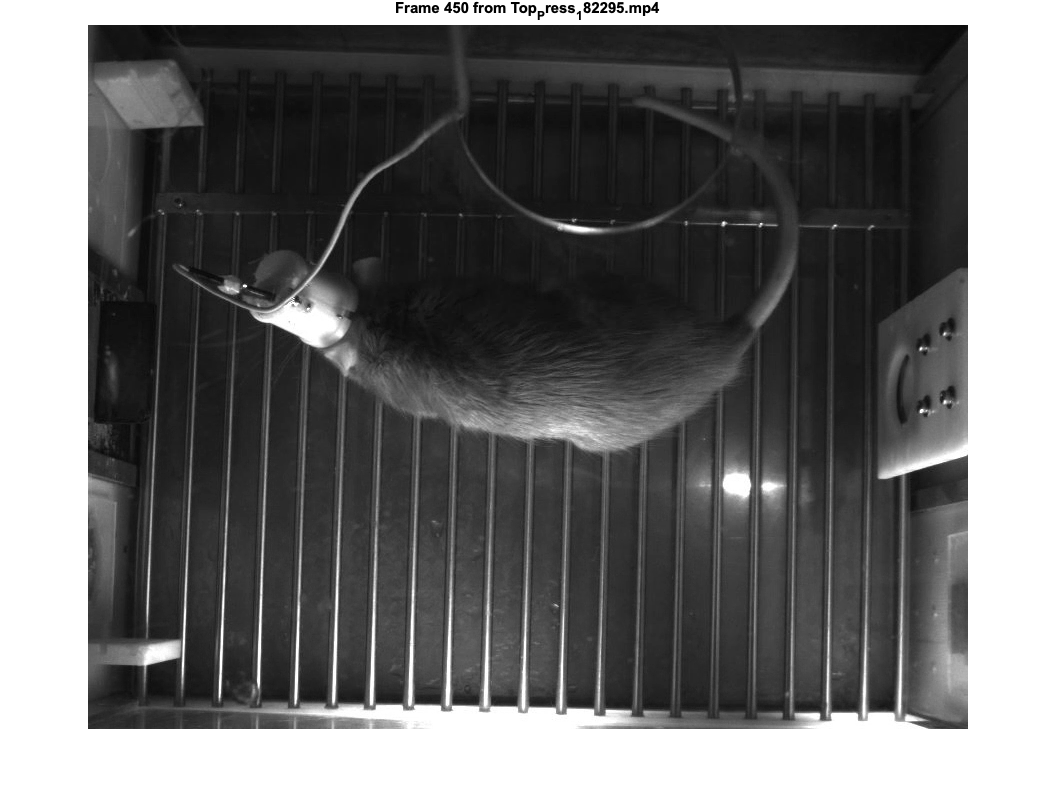

video_path = fullfile(pwd, 'Data/');
TimeStamp = '772616';
vid_name = ['Top_Press_' TimeStamp '.mp4'];
vid_meta = ['Top_Press_' TimeStamp '.mat'];
 
meta_file = load(fullfile(video_path, vid_meta));

t_toPress = 500; % 500 ms before presds
ind = find(meta_file.VideoInfo.EphysTimeStamps<meta_file.VideoInfo.Time-t_toPress, 1, 'last');

% Create VideoReader object
vid_file = fullfile(video_path, vid_name);
vidObj = VideoReader(vid_file);

% Frame index to extract
frame_index = ind;

% Read and extract the 100th frame
vidObj.CurrentTime = (frame_index - 1) / vidObj.FrameRate; % Convert frame index to time
frame = readFrame(vidObj);

% Display the extracted frame
figure;
imshow(frame);
title(sprintf('Frame %d from %s', frame_index, vid_name));

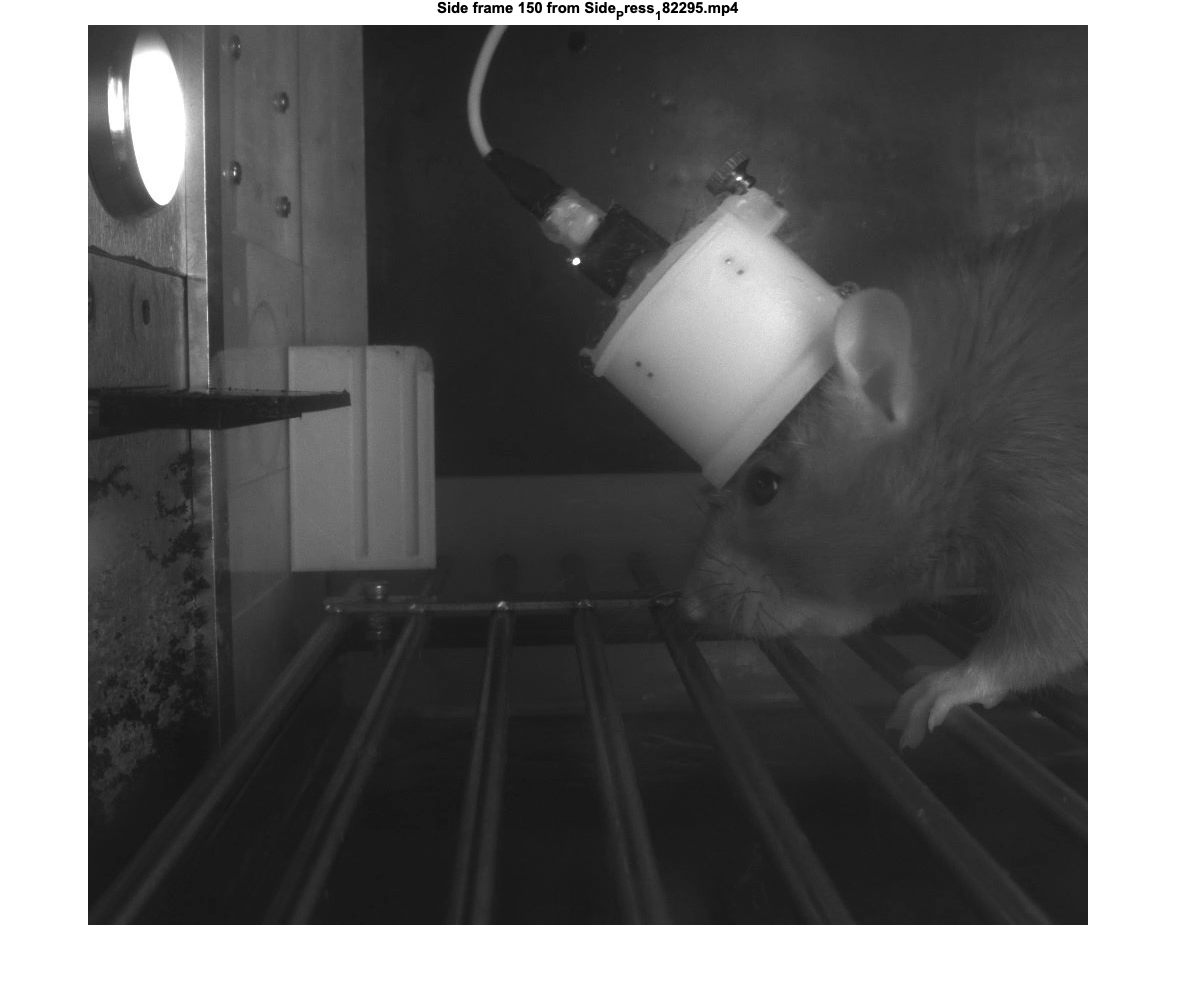

% also a side video clip
vid_name = ['Side_Press_' TimeStamp '.mp4'];
vid_meta = ['Side_Press_' TimeStamp '.mat'];

meta_file_side = load(fullfile(video_path, vid_meta));

t_toPress = 500; % 500 ms before presds
ind = find(meta_file_side.VideoInfo.EphysTimeStamps<meta_file_side.VideoInfo.Time-t_toPress, 1, 'last');

% Create VideoReader object
vid_file = fullfile(video_path, vid_name);
vidObjSide = VideoReader(vid_file);

% Frame index to extract
frame_index = ind;

% Read and extract the 100th frame
vidObjSide.CurrentTime = (frame_index - 1) / vidObj.FrameRate; % Convert frame index to time
frame = readFrame(vidObjSide);

% Display the extracted frame
figure;
imshow(frame);
title(sprintf('Side frame %d from %s', frame_index, vid_name));



% % Optionally, save the frame as an image
% output_frame_path = fullfile(video_path, sprintf('Frame_%d.png', frame_index));
% imwrite(frame, output_frame_path);
% disp(['Saved frame to: ', output_frame_path]);

% First turn spike to sdf
load(fullfile(data_path, r_name), 'r');
tReleases = cell2mat(r.PSTH.Events.Releases.Time'); % all release event times here. 

spike_notes = r.Units.SpikeNotes;
n_units = size(spike_notes, 1);
sdf_unit = struct('ch', [], 'unit', [], 'spk_time_ms', [], 't_sdf_ms', [], 'sdf', [], 'warp_out', [], 'fp', []);

% Parameters for tight_subplot
rows = n_units; cols = 1; % Number of subplots
gap = 0.05; % Gap between plots
marg_h = [0.1 0.1]; % Top and bottom margins
marg_w = [0.1 0.1]; % Left and right margins
ha = zeros(1, n_units);
tmax = 100;
kernel_width = 10; % 5 bins kernel
bin_size = 10; 
FPs=  r.BehaviorClass.MixedFP;

ind = find(spike_notes(:, 1) ==unit_of_interest(1) & spike_notes(:, 2) ==unit_of_interest(2))

ind = 2

ispk_times               =      r.Units.SpikeTimes(ind).timings;
i_df_units               =      sdf_spktimes(ispk_times, max(ispk_times)+1000, kernel_width, bin_size);
sdf_unit.ch             =      unit_of_interest(1);
sdf_unit.unit           =      unit_of_interest(2);
sdf_unit.spk_time_ms    =      ispk_times;
sdf_unit.t_sdf_ms       =      i_df_units(:, 1);
sdf_unit.sdf            =      i_df_units(:, 2);
tmax                     =      max(tmax, sdf_unit.t_sdf_ms(end)/1000);
fprintf('Ch%2.0dUnit%2.0d', spike_notes(ind, 1), spike_notes(ind, 2))

Ch 4Unit 1

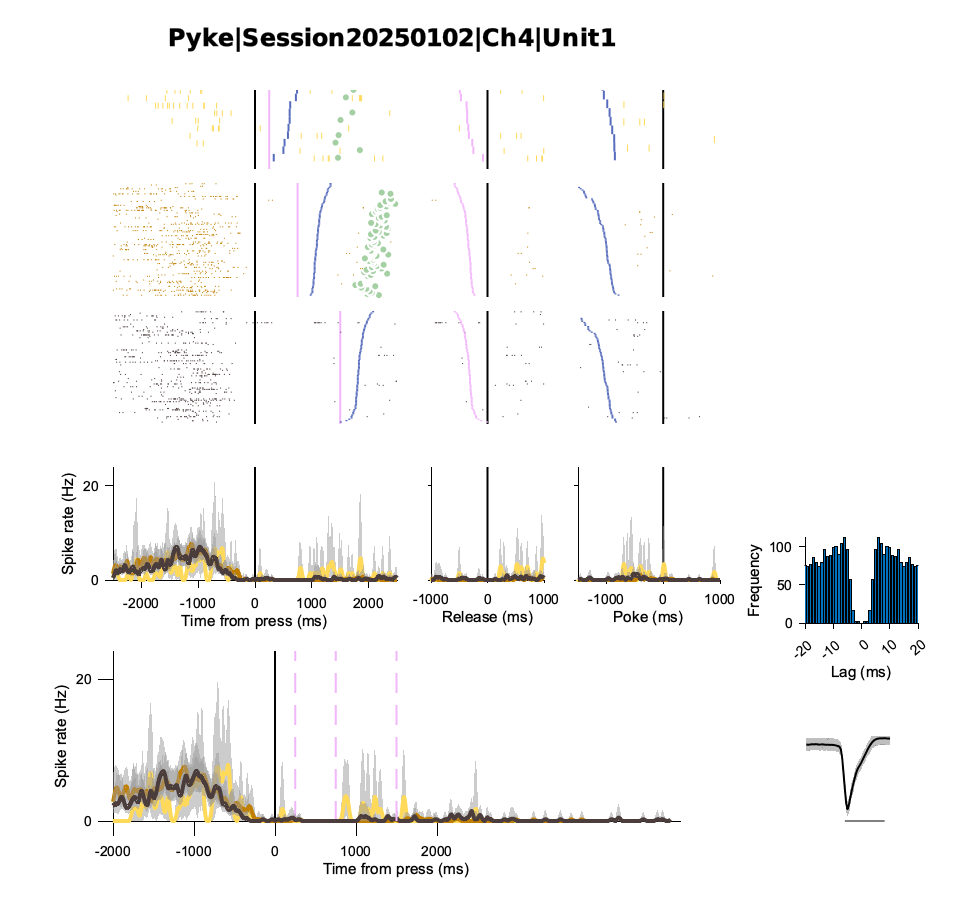

sdf_unit.warp_out = Spikes.SRT.PlotPSTHLiteWarped(r, [sdf_unit.ch sdf_unit.unit]);

sdf_unit.fp = FPs;

TimeStamp = '772616';
type = 'Approach';
TrajTableAll;
disp(spatial_span)

    50   750
    50   650



disp(tReleases);

   1.0e+06 *

    0.0096
    0.0248
    0.0362
    0.0418
    0.0603
    0.0734
    0.0826
    0.0916
    0.1010
    0.1163
    0.1271
    0.1352
    0.1436
    0.1546
    0.1677
    0.1751
    0.1839
    0.2179
    0.2305
    0.2375
    0.2579
    0.2660
    0.2747
    0.2831
    0.2917
    0.2992
    0.3067
    0.3218
    0.3397
    0.3476
    0.3565
    0.3650
    0.3761
    0.3863
    0.3953
    0.4035
    0.4114
    0.4190
    0.4258
    0.4338
    0.4411
    0.4487
    0.4540
    0.4677
    0.4758
    0.4833
    0.4904
    0.4991
    0.5067
    0.5143
    0.5305
    0.5487
    0.5584
    0.5732
    0.5795
    0.6091
    0.6181
    0.6266
    0.6362
    0.6446
    0.6840
    0.6911
    0.7176
    0.7258
    0.7358
    0.7448
    0.7523
    0.7643
    0.7744
    0.7829
    0.7917
    0.7999
    0.8024
    0.8115
    0.8195
    0.8345
    0.8459
    0.8679
    0.8763
    0.8848
    0.8927
    0.9007
    0.9085
    0.9172
    0.9265
    0.9323
    0.9422
    0.9575
    0.9665
    0.9

disp(TimeStamp)

772616


disp(video_path)

/Users/jianingyu/Dropbox/Work/VideoEphys/ANMs/DMS/Pyke/20250102/Data/


disp(unit_name)

Pyke_20250102_Ch4_Unit1


disp(type)

Approach


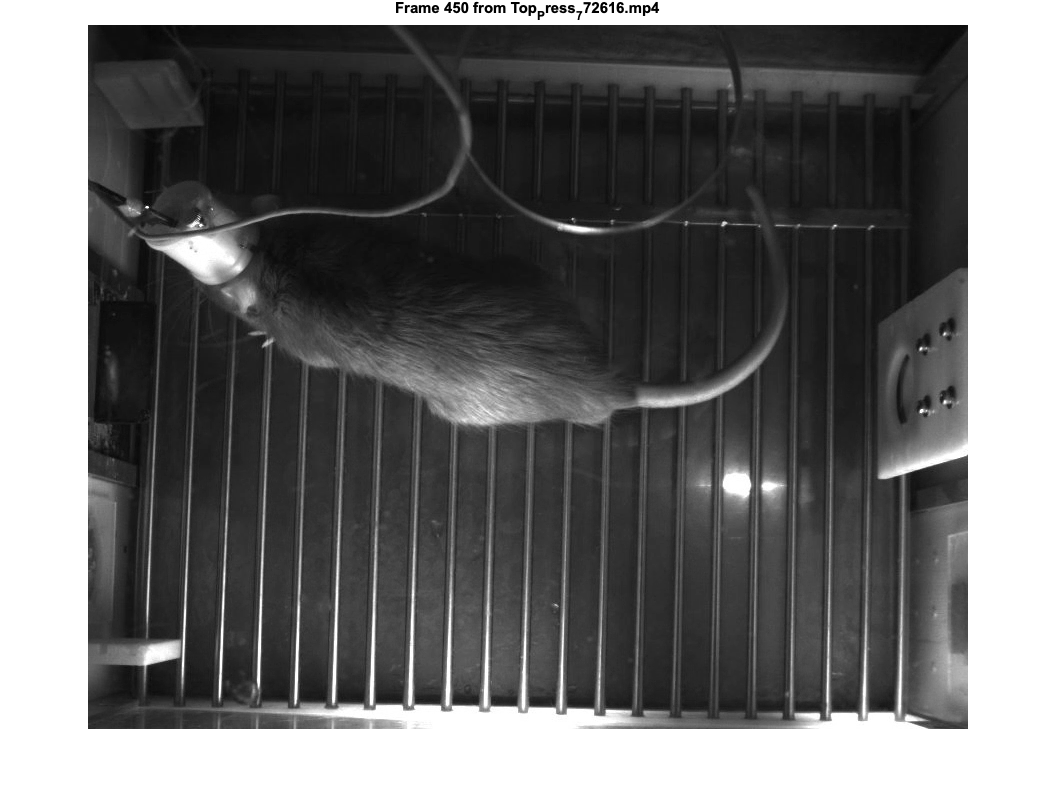

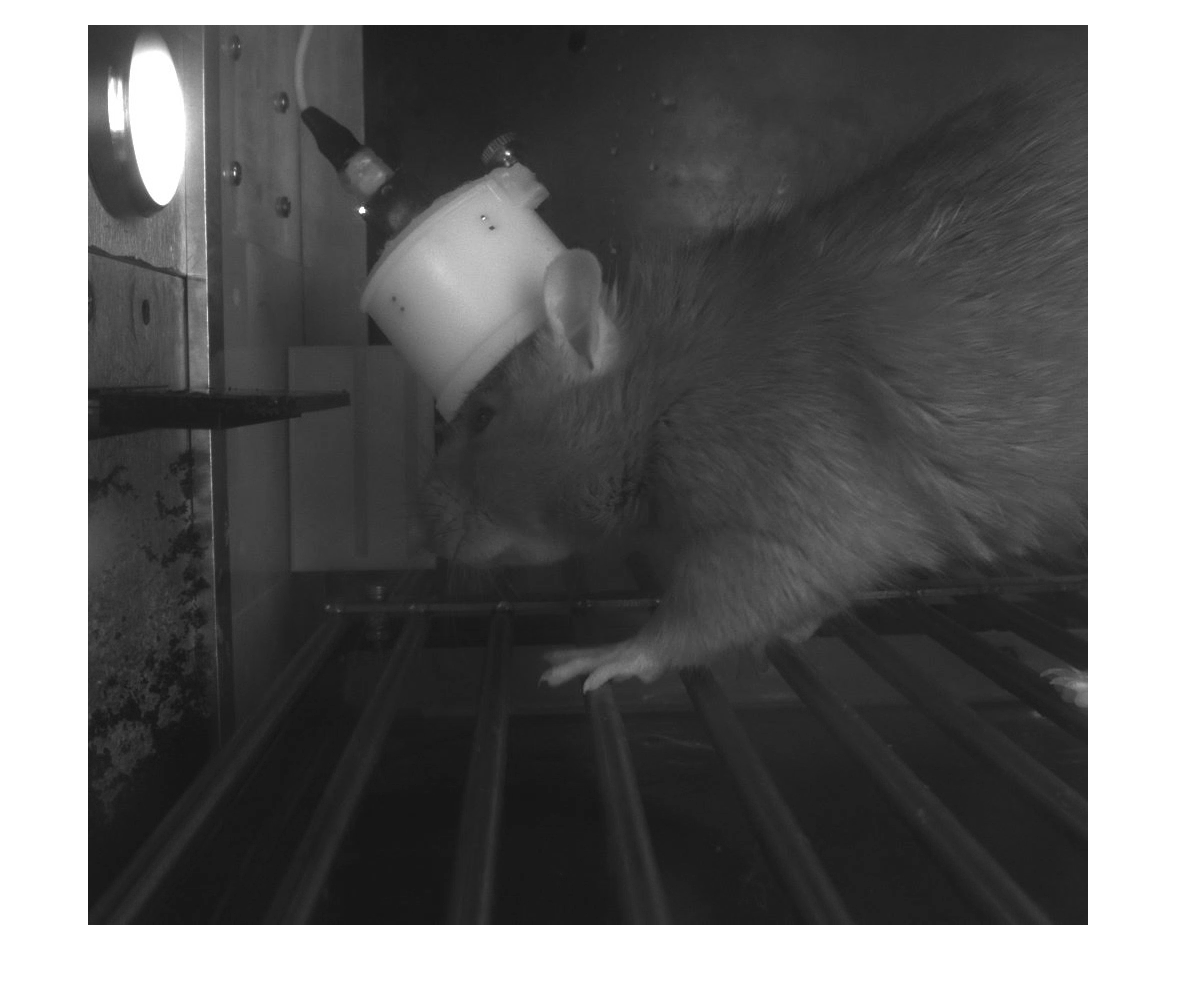

      772616

   7.7445e+05

Top_Press_772616
r = -0.039935, p = 2.6844e-05

Linear regression model:
    y ~ 1 + x1

Estimated Coefficients:
                   Estimate      SE        tStat       pValue  
                   ________    _______    _______    __________

    (Intercept)     5.9438     0.12691     46.836             0
    x1             -1.5638      0.3723    -4.2005    2.6844e-05


Number of observations: 11048, Error degrees of freedom: 11046
Root Mean Squared Error: 9.93
R-squared: 0.00159,  Adjusted R-Squared: 0.0015
F-statistic vs. constant model: 17.6, p-value = 2.68e-05


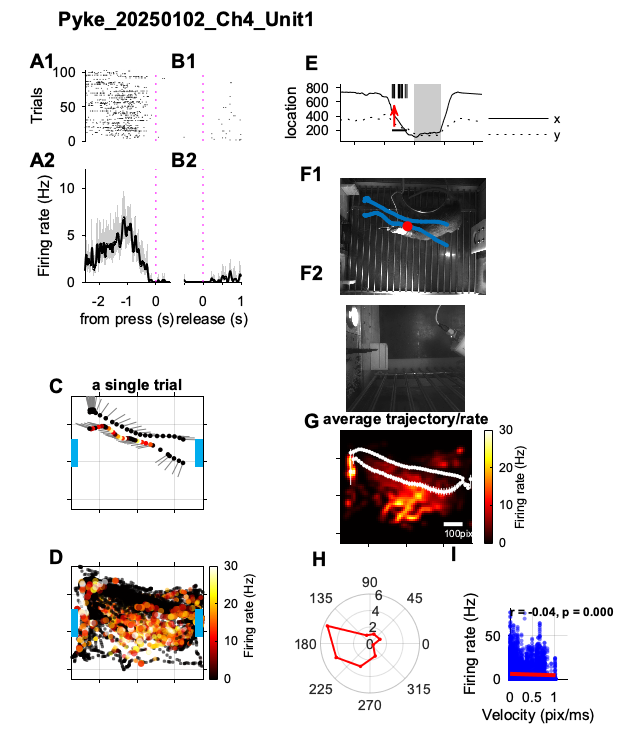

Spikes.Videos.PlotTrajectorySpikes(sdf_unit, TrajTableAll, spatial_span, tReleases, TimeStamp, video_path, unit_name, type)